# Pointwise self-convergence for a 2D multipole source

No exact solution is used. Every refinement is sampled on the same two-dimensional observation grid and at the same output times. Successive-grid differences are maximized over time, producing a spatial error indicator and observed-order map. The default experiment uses four-sided PMLs, as in the older 2D study.

clear
close all
clc

## Experiment parameters

xDomain = [0,1];
yDomain = [0,1];
finalTime = 1;

sourceLocation = [0.567,0.531]; % Off-grid on every refinement
derivativeOrder = [1,0];       % [0,0]=monopole, [1,0]=x-dipole, ...
targetField = "pressure";      % "pressure", "velocityX", or "velocityY"

% Nested pressure grids: N(k+1)-1 = 2*(N(k)-1).
pointCounts = [51,101,201];
nLevels = numel(pointCounts);
if nLevels < 3
    error('At least three grid levels are required for self-convergence.')
end

% Compare the same three accuracy combinations as the 1D study.
spatialOrders = [4,4,2];
qValues = [4,2,2];
caseLabels = ["p=4, q=4","p=4, q=2","p=2, q=2"];
nCases = numel(qValues);

% For p=2, dt=O(h), so temporal and spatial errors are both O(h^2).
% For p=4, dt=O(h^2), making the leapfrog error O(h^4).
CFL2 = 0.9;
Ctime4 = 0.9;

% All runs are sampled at exactly these times.
nOutputSteps = 200;
outputTimes = linspace(0,finalTime,nOutputSteps+1);

% Delayed Ricker pulse, negligible at t=0.
fPeak = 5;
t0 = 0.3;
sourceTime = @(t) (1-2*(pi*fPeak*(t-t0)).^2) ...
    .*exp(-(pi*fPeak*(t-t0)).^2);

medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

% true reproduces the four-sided absorbing setup of the old experiment.
% Set false to study the zero-pressure baseline solver instead.
usePML = true;
% With pointCounts=[25,49,97], rounding 0.20 upward to whole cells gives
% the same effective PML width, 5/24, on all three nested grids.
pmlWidth = 0.20;
reflectionCoefficient = 1e-6;
polynomialDegree = 3;

## Common spatial observation grid

outputGrid = GridSpace2D( ...
    Grid1DUnifPrimal(xDomain,pointCounts(1)), ...
    Grid1DUnifPrimal(yDomain,pointCounts(1)));
xOutput = outputGrid.x.pts;
yOutput = outputGrid.y.pts;
[XOutput,YOutput] = outputGrid.mesh();

## Optional diagnostic: coarsest-grid MPS stencils

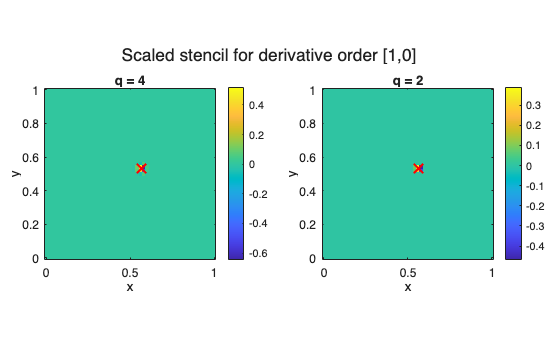

pressureGrid0 = outputGrid;
velocityXGrid0 = GridSpace2D( ...
    Grid1DUnifDual(pressureGrid0.x),pressureGrid0.y);
velocityYGrid0 = GridSpace2D( ...
    pressureGrid0.x,Grid1DUnifDual(pressureGrid0.y));

figure
layout = tiledlayout(1,numel(unique(qValues)), ...
    TileSpacing="compact",Padding="compact");
qUnique = unique(qValues,'stable');
for qIndex = 1:numel(qUnique)
    q = qUnique(qIndex);

    diagnosticCmp = MultipoleComponent2D( ...
        sourceLocation,derivativeOrder,TargetField=targetField);
    diagnosticMPS = MultipoleSrcTerm2D( ...
        diagnosticCmp,@(t) 1);
    diagnosticSource = diagnosticMPS.discretize( ...
        pressureGrid0,velocityXGrid0,velocityYGrid0,q);

    switch targetField
        case "pressure"
            stencilGrid = pressureGrid0;
            prepared = diagnosticSource.preparePressure(stencilGrid);
        case "velocityX"
            stencilGrid = velocityXGrid0;
            prepared = diagnosticSource.prepareVelocityX(stencilGrid);
        case "velocityY"
            stencilGrid = velocityYGrid0;
            prepared = diagnosticSource.prepareVelocityY(stencilGrid);
    end

    stencil = diagnosticSource.evaluatePrepared(prepared,0);
    scalePowerX = derivativeOrder(1)+1;
    scalePowerY = derivativeOrder(2)+1;
    stencil = stencil*stencilGrid.h(1)^scalePowerX ...
        *stencilGrid.h(2)^scalePowerY;

    ax = nexttile(layout);
    imagesc(ax,stencilGrid.x.pts,stencilGrid.y.pts,stencil.');
    axis(ax,'xy','image');
    colorbar(ax);
    hold(ax,'on');
    plot(ax,sourceLocation(1),sourceLocation(2),'rx', ...
        MarkerSize=10,LineWidth=1.5);
    hold(ax,'off');
    xlabel(ax,'x');
    ylabel(ax,'y');
    title(ax,sprintf('q = %d',q));
end
title(layout,sprintf('Scaled stencil for derivative order [%d,%d]', ...
    derivativeOrder(1),derivativeOrder(2)));

## Compute solutions on every grid

pressure = cell(nCases,nLevels);
hUsed = zeros(nCases,nLevels);
dtUsed = zeros(nCases,nLevels);
timeStepsUsed = zeros(nCases,nLevels);

for iCase = 1:nCases
    spatialOrder = spatialOrders(iCase);
    q = qValues(iCase);

    fprintf('\nRunning spatial order %d, MPS q=%d, derivative [%d,%d]\n', ...
        spatialOrder,q,derivativeOrder(1),derivativeOrder(2));

    for level = 1:nLevels
        n = pointCounts(level);
        pressureGrid = GridSpace2D( ...
            Grid1DUnifPrimal(xDomain,n), ...
            Grid1DUnifPrimal(yDomain,n));
        velocityXGrid = GridSpace2D( ...
            Grid1DUnifDual(pressureGrid.x),pressureGrid.y);
        velocityYGrid = GridSpace2D( ...
            pressureGrid.x,Grid1DUnifDual(pressureGrid.y));
        h = max(pressureGrid.h);

        if spatialOrder == 2
            targetDt = CFL2/(sqrt(sum(1./pressureGrid.h.^2)));
        else
            targetDt = Ctime4*h^2;
        end
        nTimeSteps = ceil(finalTime/targetDt);
        computationalTimes = linspace(0,finalTime,nTimeSteps+1);

        mps_cmp = MultipoleComponent2D( ...
            sourceLocation,derivativeOrder,TargetField=targetField);
        mps = MultipoleSrcTerm2D(mps_cmp,sourceTime);
        source = mps.discretize( ...
            pressureGrid,velocityXGrid,velocityYGrid,q);

        if usePML
            pml = PML2D( ...
                WidthLeft=pmlWidth,WidthRight=pmlWidth, ...
                WidthBottom=pmlWidth,WidthTop=pmlWidth, ...
                ReflectionCoefficient=reflectionCoefficient, ...
                PolynomialDegree=polynomialDegree);
            solver = AcousticSolver2D_PML( ...
                pressureGrid,computationalTimes, ...
                outputGrid,outputTimes,medium,pml, ...
                SpatialOrder=spatialOrder);
        else
            solver = AcousticSolver2DStaggered( ...
                pressureGrid,computationalTimes, ...
                outputGrid,outputTimes,medium, ...
                SpatialOrder=spatialOrder);
        end

        [P,~,~] = solver.solve(p0,vx0,vy0,Source=source);
        pressure{iCase,level} = P.values;
        hUsed(iCase,level) = h;
        dtUsed(iCase,level) = computationalTimes(2) ...
            -computationalTimes(1);
        timeStepsUsed(iCase,level) = nTimeSteps;

        fprintf('  N=%4d, h=%9.3e, dt=%9.3e, steps=%d\n', ...
            n,h,dtUsed(iCase,level),nTimeSteps);
    end
end


Running spatial order 4, MPS q=4, derivative [1,0]


  N=  51, h=2.000e-02, dt=3.600e-04, steps=2778
  N= 101, h=1.000e-02, dt=8.999e-05, steps=11112
  N= 201, h=5.000e-03, dt=2.250e-05, steps=44445



Running spatial order 4, MPS q=2, derivative [1,0]


  N=  51, h=2.000e-02, dt=3.600e-04, steps=2778
  N= 101, h=1.000e-02, dt=8.999e-05, steps=11112
  N= 201, h=5.000e-03, dt=2.250e-05, steps=44445



Running spatial order 2, MPS q=2, derivative [1,0]


  N=  51, h=2.000e-02, dt=1.266e-02, steps=79
  N= 101, h=1.000e-02, dt=6.329e-03, steps=158
  N= 201, h=5.000e-03, dt=3.175e-03, steps=315


## Successive-grid differences and pointwise rate maps

% difference{iCase,level} compares levels level and level+1:
%   E_h(x,y) = max_t |p_h(x,y,t)-p_{h/2}(x,y,t)|.
difference = cell(nCases,nLevels-1);
rate = cell(nCases,nLevels-2);

solutionScale = 1;
for iCase = 1:nCases
    for level = 1:nLevels
        solutionScale = max(solutionScale, ...
            max(abs(pressure{iCase,level}),[],'all'));
    end
end
differenceFloor = 1e3*eps(solutionScale);

for iCase = 1:nCases
    for level = 1:nLevels-1
        difference{iCase,level} = max(abs( ...
            pressure{iCase,level}-pressure{iCase,level+1}),[],3);
    end

    for level = 1:nLevels-2
        coarseDifference = difference{iCase,level};
        fineDifference = difference{iCase,level+1};
        rateHere = nan(outputGrid.N);
        reliable = coarseDifference > differenceFloor & ...
            fineDifference > differenceFloor;
        refinementRatio = hUsed(iCase,level) ...
            /hUsed(iCase,level+1);
        rateHere(reliable) = log( ...
            coarseDifference(reliable)./fineDifference(reliable)) ...
            /log(refinementRatio);
        rate{iCase,level} = rateHere;
    end
end

## Successive-grid difference maps

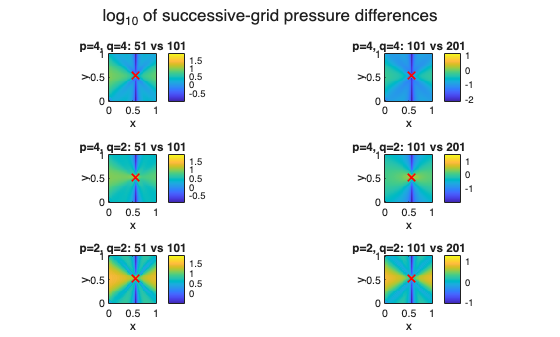

figure
layout = tiledlayout(nCases,nLevels-1, ...
    TileSpacing="compact",Padding="compact");
for iCase = 1:nCases
    for level = 1:nLevels-1
        ax = nexttile(layout);
        imagesc(ax,xOutput,yOutput, ...
            log10(max(difference{iCase,level},differenceFloor)).');
        axis(ax,'xy','image');
        colorbar(ax);
        hold(ax,'on');
        plot(ax,sourceLocation(1),sourceLocation(2),'rx', ...
            MarkerSize=8,LineWidth=1.3);
        hold(ax,'off');
        xlabel(ax,'x');
        ylabel(ax,'y');
        title(ax,sprintf('%s: %d vs %d',caseLabels(iCase), ...
            pointCounts(level),pointCounts(level+1)));
    end
end
title(layout,'log_{10} of successive-grid pressure differences');

## Pointwise self-convergence rate maps

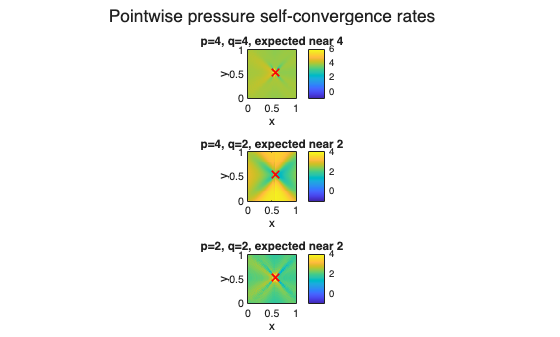

figure
layout = tiledlayout(nCases,nLevels-2, ...
    TileSpacing="compact",Padding="compact");
for iCase = 1:nCases
    expectedOrder = min(spatialOrders(iCase),qValues(iCase));
    for level = 1:nLevels-2
        ax = nexttile(layout);
        imagesc(ax,xOutput,yOutput,rate{iCase,level}.');
        axis(ax,'xy','image');
        clim(ax,[-1,expectedOrder+2]);
        colorbar(ax);
        hold(ax,'on');
        plot(ax,sourceLocation(1),sourceLocation(2),'rx', ...
            MarkerSize=8,LineWidth=1.3);
        hold(ax,'off');
        xlabel(ax,'x');
        ylabel(ax,'y');
        title(ax,sprintf('%s, expected near %d', ...
            caseLabels(iCase),expectedOrder));
    end
end
title(layout,'Pointwise pressure self-convergence rates');

## Centerline rate traces

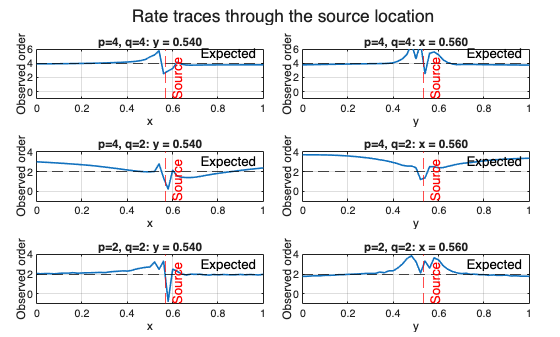

 [~,sourceXIndex] = min(abs(xOutput-sourceLocation(1)));
[~,sourceYIndex] = min(abs(yOutput-sourceLocation(2)));

figure
layout = tiledlayout(nCases,2,TileSpacing="compact",Padding="compact");
for iCase = 1:nCases
    expectedOrder = min(spatialOrders(iCase),qValues(iCase));
    rateMap = rate{iCase,end};

    ax = nexttile(layout);
    plot(ax,xOutput,rateMap(:,sourceYIndex),LineWidth=1.2);
    yline(ax,expectedOrder,'--k','Expected');
    xline(ax,sourceLocation(1),'--r','Source');
    ylim(ax,[-1,expectedOrder+2]);
    xlabel(ax,'x');
    ylabel(ax,'Observed order');
    title(ax,sprintf('%s: y = %.3f', ...
        caseLabels(iCase),yOutput(sourceYIndex)));
    grid(ax,'on');

    ax = nexttile(layout);
    plot(ax,yOutput,rateMap(sourceXIndex,:),LineWidth=1.2);
    yline(ax,expectedOrder,'--k','Expected');
    xline(ax,sourceLocation(2),'--r','Source');
    ylim(ax,[-1,expectedOrder+2]);
    xlabel(ax,'y');
    ylabel(ax,'Observed order');
    title(ax,sprintf('%s: x = %.3f', ...
        caseLabels(iCase),xOutput(sourceXIndex)));
    grid(ax,'on');
end
title(layout,'Rate traces through the source location');

## Compact rate summary

% Exclude a small neighborhood of the singular source from the summary.
exclusionRadius = 4*max(outputGrid.h);
awayFromSource = hypot(XOutput-sourceLocation(1), ...
    YOutput-sourceLocation(2)) >= exclusionRadius;

medianRate = nan(nCases,nLevels-2);
reliablePointFraction = nan(nCases,nLevels-2);
for iCase = 1:nCases
    for level = 1:nLevels-2
        values = rate{iCase,level};
        included = awayFromSource & isfinite(values);
        medianRate(iCase,level) = median(values(included),'omitnan');
        reliablePointFraction(iCase,level) = ...
            nnz(included)/nnz(awayFromSource);
    end
end

spatialOrderColumn = repelem(spatialOrders(:),nLevels-2);
qColumn = repelem(qValues(:),nLevels-2);
coarseNColumn = repmat(pointCounts(1:end-2).',nCases,1);
middleNColumn = repmat(pointCounts(2:end-1).',nCases,1);
fineNColumn = repmat(pointCounts(3:end).',nCases,1);
medianRateColumn = reshape(medianRate.',[],1);
reliableFractionColumn = reshape(reliablePointFraction.',[],1);

summaryTable = table( ...
    spatialOrderColumn,qColumn,coarseNColumn,middleNColumn, ...
    fineNColumn,medianRateColumn,reliableFractionColumn, ...
    'VariableNames',{'SpatialOrder','q','CoarseN','MiddleN','FineN', ...
    'MedianPointwiseRate','ReliablePointFraction'})

summaryTable = 3×7 table
    SpatialOrder    q    CoarseN    MiddleN    FineN    MedianPointwiseRate    ReliablePointFraction
    ____________    _    _______    _______    _____    ___________________    _____________________

         4          4      51         101       201           3.9217                     1          
         4          2      51         101       201           2.6858                     1          
         2          2      51         101       201           2.1368                     1          

	Get insights using Copilot
